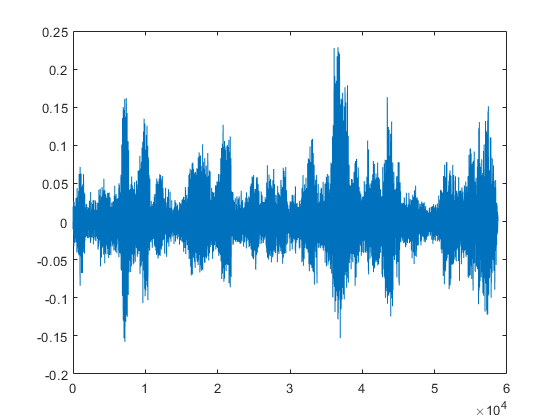

clear;
close all;
clc;
format long;

dirname = 'sample11/';
outname = [dirname, 'enhan.wav'];
orig_outname = [dirname, 'orig_enhan.wav'];
paths = csvimport([dirname, 'wav.list'],'columns', {'path'});

[x1, sr] = audioread(paths{1});
[x2, sr] = audioread(paths{2});
[x3, sr] = audioread(paths{3});
[x4, sr] = audioread(paths{4});
[x5, sr] = audioread(paths{5});

x = [x1, x2, x3, x4, x5];
x = x';
nsample = size(x,2);
nmic = 5;
%npair = nmic - 1;
npair = nmic;

figure;plot(x(1,:));

## make hamming window

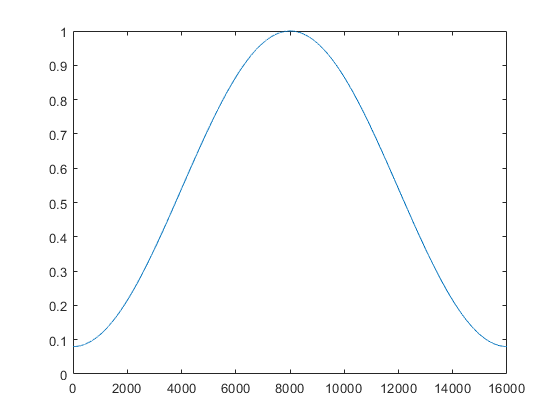

nwin = 16000; % 1 sec
%     hamm_val = 0.54 - 0.46*cos(6.283185307*i/(window-1));
win = zeros(1,nwin);
for i = 1:nwin
    win(i) = 0.54 - 0.46 * cos(6.283185307*(i-1)/(nwin-1));
end

figure; plot(win);

disp(win(1:10));

  1 ~ 3번 열

   0.080000000000000   0.080000035473324   0.080000141893292

  4 ~ 6번 열

   0.080000319259887   0.080000567573081   0.080000886832836

  7 ~ 9번 열

   0.080001277039103   0.080001738191823   0.080002270290922

  10번 열

   0.080002873336321



## testing calculating xcorr

npiece = 200;
nfft = 16384*2;
nbest = 2;
nmask = 5;
scroll = floor(nsample / (npiece+2)); 

stft1 = fft([x(1,scroll+1:(scroll+nwin)) .* win, zeros(1,nfft-nwin)]); 
stft2 = fft([x(2,scroll+1:(scroll+nwin)) .* win, zeros(1,nfft-nwin)]); 

numerator = stft1 .* conj(stft2);
ccorr = real(ifft(numerator ./ (abs(numerator))));
ccorr = [ccorr(end-479:end), ccorr(1:480)];

[best_ccorr, best_idx] = maxk(ccorr, nbest, nmask);
disp(scroll);

   290



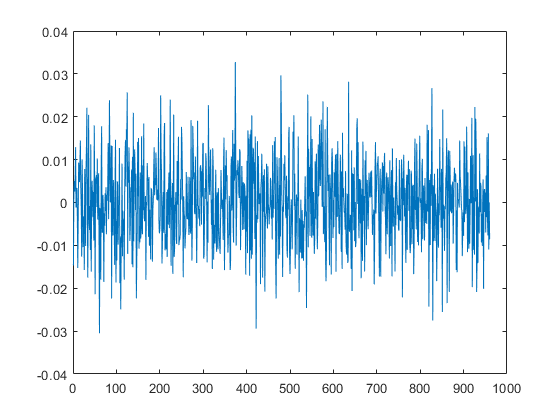

plot(ccorr);


disp(best_ccorr);

   0.032781450919252
   0.029635834307374



## calculate avg_ccorr

avg_ccorr = zeros(nmic, nmic);


for i = 1:npiece
    st = i * scroll + 1;
    ed = st + 16000 - 1;
    if st + 16384 >= nsample
        break;
    end

    for m1 = 1:(nmic-1)
        avg_ccorr(m1, m1) = 0;
        for m2 = (m1+1):nmic
            stft1 = fft([x(m1,st:ed) .* win, zeros(1,nfft-nwin)]); 
            stft2 = fft([x(m2,st:ed) .* win, zeros(1,nfft-nwin)]);
            numerator = stft1 .* conj(stft2);
            ccorr = real(ifft(numerator ./ (abs(numerator))));
            ccorr = [ccorr(end-479:end), ccorr(1:480)];

            maxk_val = sum(maxk(ccorr, nbest, nmask));
            
            avg_ccorr(m1, m2) = avg_ccorr(m1, m2) + (maxk_val);
            avg_ccorr(m2, m1) = avg_ccorr(m1, m2); 
        end
    end
end

avg_ccorr = avg_ccorr / (nbest * npiece);

disp(avg_ccorr);

  1 ~ 3번 열

                   0   0.022342359302499   0.038002415483785
   0.022342359302499                   0   0.078103387449447
   0.038002415483785   0.078103387449447                   0
   0.159321275205544   0.021976501561010   0.038497480480202
   0.116734197033740   0.022246232748426   0.034219510992536

  4 ~ 5번 열

   0.159321275205544   0.116734197033740
   0.021976501561010   0.022246232748426
   0.038497480480202   0.034219510992536
                   0   0.153034492978611
   0.153034492978611                   0



fprintf('%.8f\n', sum(avg_ccorr/nmic));

0.06728005
0.02893370
0.03776456
0.07456595
0.06524689


disp(sum(avg_ccorr,1));

  1 ~ 3번 열

   0.336400247025568   0.144668481061382   0.188822794405971

  4 ~ 5번 열

   0.372829750225366   0.326234433753313



disp(sum(avg_ccorr,1)/nmic);

  1 ~ 3번 열

   0.067280049405114   0.028933696212276   0.037764558881194

  4 ~ 5번 열

   0.074565950045073   0.065246886750663




[dummy, ref_mic] = max(sum(avg_ccorr));

disp(ref_mic); 

     4



## calculating scaling factor

nsegment = 10;

max_val = zeros(nmic, 1);

if size(x,2) <= 160000 % 10 seconds
    for m = 1:nmic
        max_val(m) = max(abs(x(m,:)));
    end
else
    if size(x,2) < 1600000 % 100 seconds
        nsegment = floor(size(x,2) / 160000);
    end
    
    scroll = floor(size(x,2) / nsegment);
    max_val_candidate = zeros(nmic, nsegment);
    
    for s = 0:(nsegment-1)
        st = s * scroll + 1;
        ed = st + 160000 - 1;
        for m = 1:nmic
            max_val_candidate(m,s+1) = max(abs(x(m,st:ed)));
        end
    end
    
    for m = 1:nmic
        
        sorted = sort(max_val_candidate(m,:), 'ascend');
        if length(sorted(:)) > 2
            max_val(m) = sorted(end/2 + 1);
        else
            max_val(m) = sorted;
        end
    end
end

overall_weight = (0.3 * nmic) / sum(max_val);

disp(max_val');

  1 ~ 3번 열

   0.228759765625000   1.000000000000000   0.025970458984375

  4 ~ 5번 열

   0.115905761718750   0.138183593750000



disp(overall_weight);

   0.994154648975547



## compute total number of delays

% int totalNumDelays
% % = (int)((m_frames - (*m_config).windowFrames - m_biggestSkew - m_UEMGap)/((*m_config).
% rate*m_sampleRateInMs));
% sr_in_ms = 16000 / 1000; % 16

% too complicated. I should do hard coding
nframe = floor(( nsample - 8000 ) / (4000));

disp(nframe);

    12



## recreating hamming window

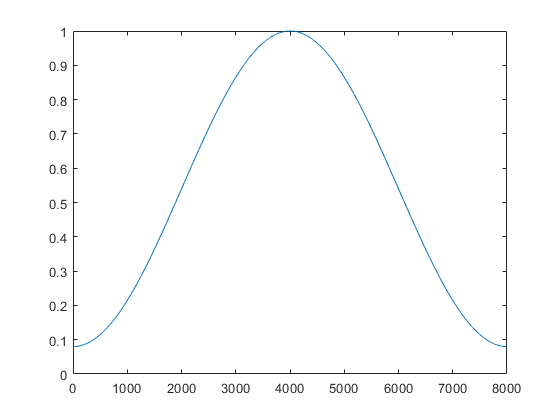

nwin = 8000; % 0.5 sec
nfft = 16384;

win = zeros(1,nwin);
for i = 1:nwin
    win(i) = 0.54 - 0.46 * cos(6.283185307*(i-1)/(nwin-1));
end

figure; plot(win);

% Marginst for delays in frames: 480 in ms: 30
disp(16000 * 30 / 1000);

   480



## compute TDOA

nbest = 4;

micpair = zeros(nmic, npair);

gcc_nbest = zeros(npair, nframe, nbest);
tdoa_nbest = zeros(npair, nframe, nbest);
lrfilp_gcc = zeros(npair, nframe, nfft);

for m = 1:nmic
    p = 1; % pair idx
    for i = 1:nmic

        micpair(m,p) = i;
        p = p + 1;
    end
end


for t = 1:(nframe)
    st = (t-1) * 4000 + 1;
    ed = st + nwin - 1;

        for p = 1:npair
            
            m = micpair(ref_mic,p);
            
            stft_ref = fft([x(ref_mic,st:ed) .* win, zeros(1,nfft-nwin)]); 
            stft_m = fft([x(m,st:ed) .* win, zeros(1,nfft-nwin)]);
            numerator = stft_m .* conj(stft_ref);
            gcc = real(ifft(numerator ./ (eps+abs(numerator))));
            gcc = [gcc(end-479:end), gcc(1:480)];
            [gcck, tdoak] = maxk(gcc, nbest, nmask);
            gcc_nbest(p,t,:) = gcck;
            tdoa_nbest(p,t,:) = tdoak;
            tdoa_nbest(p,t,:) = tdoa_nbest(p,t,:) - (481); % index shifting
          
        end

end

disp(squeeze(gcc_nbest(:,:,1)));

  1 ~ 3번 열

   0.134777527147523   0.310714006511790   0.314917088716397
   0.038170132109127   0.038882672962859   0.040929068935400
   0.036834531567438   0.070516117486481   0.065935288669931
   0.999999999981588   0.999999999988105   0.999999999914246
   0.172777734235956   0.241398231239069   0.262939287365895

  4 ~ 6번 열

   0.219783203852808   0.305739643099305   0.205989675419255
   0.040529452208426   0.040242533837290   0.038297009643333
   0.058450959230501   0.047566424970544   0.043482510827778
   0.999999999989013   0.999999999980583   0.999999999942182
   0.214451989280496   0.220126884800238   0.204886564654973

  7 ~ 9번 열

   0.139442190097295   0.247661604455948   0.235643518139056
   0.045184767676717   0.040162493825616   0.046668417418980
   0.068271058129833   0.080619738420894   0.084556027188915
   0.999999999973040   0.999999999993713   0.999999999028075
   0.207187769957736   0.253262170513861   0.268108220115873

  10 ~ 12번 열

   0.169198224556999   0.1281404

disp(squeeze(gcc_nbest(:,:,2)));

  1 ~ 3번 열

   0.114963745017336   0.195475855758566   0.178648556747342
   0.035116742147854   0.037100053263609   0.035637360007886
   0.035679446602257   0.055503548679856   0.061724224597425
   0.000000000017548   0.000000000011468   0.000000000083928
   0.133339519236832   0.200525040686099   0.241082840169924

  4 ~ 6번 열

   0.158157287770155   0.260599768920549   0.205012091175727
   0.038385342961917   0.039096335915366   0.034038067625336
   0.050090393606936   0.047073220807878   0.037751163946570
   0.000000000010134   0.000000000018172   0.000000000053912
   0.166791715526935   0.208421232232020   0.202540786009772

  7 ~ 9번 열

   0.138911452036715   0.223651054016421   0.231282995204979
   0.044228359122572   0.036658221849904   0.045221332635653
   0.053995335553000   0.042618306301619   0.076562882452097
   0.000000000026109   0.000000000005186   0.000000000965135
   0.145884405215472   0.195681079491320   0.188905560986978

  10 ~ 12번 열

   0.158667153198419   0.1016852


disp(squeeze(tdoa_nbest(:,:,1)));

    -6     0     0     0     0    -5    -5     0    -5    -5    -8     0
   267     4  -464  -204   416   101   -75  -367  -354   175   393  -383
  -283    -1    -3  -316    39    -1    -5    -1     7    -1  -101     3
     0     0     0     0     0     0     0     0     0     0     0     0
     2    -4    -4     2    -4     2     2     2     2     2    -4     4



disp(squeeze(tdoa_nbest(:,:,2)));

     0    -5    -8    -5    -5     0     0    -5     0     0     0    -5
   475   -33   365  -114   389  -265    15   242   290   266   191   232
    68    -6     5    -5    -1   318   -27  -122    -1     7  -222    -5
     5    -5    -5     5    -5    -5     5    -5    -5     5     5     5
    -4     1     4    -4     2    -4    -4    -3    -3    -4     4    -1



## find noise threshold

th_idx = floor((0.1 * nframe)) + 1;

sorted = sort(sum(gcc_nbest(:,:,1),1) - sum(gcc_nbest(ref_mic,:,1),1), 'ascend');

threshold = sorted(th_idx)/(nmic-1);

% Computing the optimum delays
disp(threshold);

   0.098250683756843



## noise filtering

noise_filter = zeros(npair, nframe);

for p = 1:npair
    for t = 1:nframe
        if gcc_nbest(p,t,1) < threshold
            noise_filter(p,t) = 1;
            if t == 1  % it's silence
                gcc_nbest(p,t,:) = 0; % masking with discouraging values
                gcc_nbest(p,t,1) = 1; % only one path
                tdoa_nbest(p,t,:) = 480; % masking with discouraging values
                tdoa_nbest(p,t,1) = 0;
            else
                tdoa_nbest(p,t,:) = tdoa_nbest(p,t-1,:);
            end
            
            
        end
        if p == ref_mic
            gcc_nbest(p,t,:) = 0; % masking with discouraging values
            gcc_nbest(p,t,1) = 1; % only one path
            tdoa_nbest(p,t,:) = 0; 
        end
    end
end

disp(gcc_nbest(:,:,1));

  1 ~ 3번 열

   0.134777527147523   0.310714006511790   0.314917088716397
   1.000000000000000   0.038882672962859   0.040929068935400
   1.000000000000000   0.070516117486481   0.065935288669931
   1.000000000000000   1.000000000000000   1.000000000000000
   0.172777734235956   0.241398231239069   0.262939287365895

  4 ~ 6번 열

   0.219783203852808   0.305739643099305   0.205989675419255
   0.040529452208426   0.040242533837290   0.038297009643333
   0.058450959230501   0.047566424970544   0.043482510827778
   1.000000000000000   1.000000000000000   1.000000000000000
   0.214451989280496   0.220126884800238   0.204886564654973

  7 ~ 9번 열

   0.139442190097295   0.247661604455948   0.235643518139056
   0.045184767676717   0.040162493825616   0.046668417418980
   0.068271058129833   0.080619738420894   0.084556027188915
   1.000000000000000   1.000000000000000   1.000000000000000
   0.207187769957736   0.253262170513861   0.268108220115873

  10 ~ 12번 열

   0.169198224556999   0.1281404

disp(tdoa_nbest(:,:,1));

    -6     0     0     0     0    -5    -5     0    -5    -5    -8     0
     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0
     2    -4    -4     2    -4     2     2     2     2     2    -4     4




disp(gcc_nbest(:,:,2));

  1 ~ 3번 열

   0.114963745017336   0.195475855758566   0.178648556747342
                   0   0.037100053263609   0.035637360007886
                   0   0.055503548679856   0.061724224597425
                   0                   0                   0
   0.133339519236832   0.200525040686099   0.241082840169924

  4 ~ 6번 열

   0.158157287770155   0.260599768920549   0.205012091175727
   0.038385342961917   0.039096335915366   0.034038067625336
   0.050090393606936   0.047073220807878   0.037751163946570
                   0                   0                   0
   0.166791715526935   0.208421232232020   0.202540786009772

  7 ~ 9번 열

   0.138911452036715   0.223651054016421   0.231282995204979
   0.044228359122572   0.036658221849904   0.045221332635653
   0.053995335553000   0.042618306301619   0.076562882452097
                   0                   0                   0
   0.145884405215472   0.195681079491320   0.188905560986978

  10 ~ 12번 열

   0.158667153198419   0.1016852

disp(tdoa_nbest(:,:,2));

     0    -5    -8    -5    -5     0     0    -5     0     0     0    -5
   480   480   480   480   480   480   480   480   480   480   480   480
   480   480   480   480   480   480   480   480   480   480   480   480
     0     0     0     0     0     0     0     0     0     0     0     0
    -4     1     4    -4     2    -4    -4    -3    -3    -4     4    -1



## single channel viterbi - emission, trans prob

emission1 = zeros(npair, nframe, nbest);
diff1 = zeros(npair, nframe, nbest, nbest); % do not using 1st idx
transition1 = zeros(npair, nframe, nbest, nbest); % do not using 1st idx

for p = 1:npair
    for t = 1:nframe
        for n = 1:nbest 
            if gcc_nbest(p,t,n) <= 0
                emission1(p,t,n) = -1000;
            else
                emission1(p,t,n) = log10(gcc_nbest(p,t,n) / sum(gcc_nbest(p,t,:)));
            end
        end
    end
end



for p = 1:npair
    for t = 2:nframe
        for n = 1:nbest
            for nprev = 1:nbest
                diff1(p,t,n,nprev) = abs(tdoa_nbest(p,t,n) - tdoa_nbest(p,t-1,nprev));
            end
        end
    end
end

for p = 1:npair
    for t = 2:nframe
        for n = 1:nbest
            for nprev = 1:nbest
                % there is a computational bug.
%                 disp((2+maxdiff1(p,t,n)));
%                 disp(diff1(p,t,n,nprev));
%                 disp(maxdiff1(p,t,n));
%                 disp(log10(481/482));
%                 disp(1 + maxdiff1(p,t,n) - diff1(p,t,n,nprev));
%                 disp((2+maxdiff1(p,t,n)));
                maxdiff1 = max(diff1(p,t,:));
                nume = (1 + maxdiff1 - diff1(p,t,n,nprev));
                deno = (2 + maxdiff1);
                transition1(p,t,n,nprev) = log(nume / deno) / log(10); 
            end
        end
    end
end


## single channel viterbi - searching


nbest2 = 2;
score1 = zeros(npair, nframe, nbest, nbest); % tmp variable
score1_table = zeros(npair, nframe, nbest);
back1_table = zeros(npair, nframe, nbest);
bestpath1 = zeros(npair, nframe, nbest2); % state idx stored.

% original beamformit
dC = ones(npair, nframe, nbest) * -1000;
tC = ones(npair, nframe, nbest);
viterbi_score = zeros(npair, 1);

R = ones(npair, nframe); % best prev state
F = ones(npair, nframe);

forwardTrans = zeros(npair, nframe, nbest);
selfLoopTrans = zeros(npair, nframe, nbest);

bestpath1(:,:,1) = 1;
bestpath1(:,:,2) = 2;

for p = 1:npair
    for n = 1:nbest
        score1(p,1,n,:) = emission1(p,1,n); % broadcasting
        score1_table(p,1,n) = emission1(p,1,n);
    end
end

for p = 1:npair
    for n = 1:nbest
        dC(p,1,n) = emission1(p,1,n);
    end
end

for p = 1:npair
    for t = 2:nframe
        for n = 1:nbest
            best_n_prev = R(p,t-1);
            back1_table(p,t,1) = best_n_prev;
            
            forwardTrans(p,t,n) = dC(p,t-1,best_n_prev) + 25 * transition1(p,t,n,best_n_prev);
            selfLoopTrans(p,t,n) = dC(p,t-1,n) + 25 * transition1(p,t,n,n);
            
            if selfLoopTrans(p,t,n) >= forwardTrans(p,t,n)
                dC(p,t,n) = selfLoopTrans(p,t,n) + emission1(p,t,n);
                tC(p,t,n) = tC(p,t-1,n);
            else
                dC(p,t,n) = forwardTrans(p,t,n) + emission1(p,t,n);
                tC(p,t,n) = t;
            end
        end
        
        [dummy, R(p,t)] = max(dC(p,t,:));
        F(p,t) = tC(p,t,R(p,t));
        
    end
    
    st = F(p,end);
    bestpath1(p,st:end,1) = R(p,end);
    
    while st > 2
        ed = st - 1;
        st = F(p,ed);
        bestpath1(p,st:ed,1) = R(p,ed);
    end
    
    viterbi_score(p) = dC(p,end,R(p,end));
    
end


disp(bestpath1(:,:,1));

     1     1     1     1     1     2     2     1     2     2     2     1
     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     2     1     2     2     2     2     2     1     1



disp(viterbi_score');

  1 ~ 3번 열

  -8.177195798314624  -6.512432585836903  -5.781413084413090

  4 ~ 5번 열

 -82.783248807594831 -10.422622989494176



## single channel viterbi - 2-best path


gcc_nbest_copy = gcc_nbest;
emission1_copy = emission1;
bestpath1(:,:,2) = bestpath1(:,:,1);

for p = 1:npair
    for t = 1:nframe
        best1 = bestpath1(p,t,1);
        gcc_nbest_copy(p,t,best1) = 0;
    end
end

for p = 1:npair
    for t = 1:nframe
        for n = 1:nbest 
            if gcc_nbest_copy(p,t,n) > 0    
                emission1_copy(p,t,n) = log10(gcc_nbest_copy(p,t,n) / sum(gcc_nbest_copy(p,t,:)));
            else
                emission1_copy(p,t,n) = -1000;
            end
        end
    end
end

dC = zeros(npair, nframe, nbest);
tC = ones(npair, nframe, nbest);
viterbi_score = zeros(npair, 1);

R = ones(npair, nframe); % best prev state
F = ones(npair, nframe);

forwardTrans = zeros(npair, nframe, nbest);
selfLoopTrans = zeros(npair, nframe, nbest);

for p = 1:npair
    for n = 1:nbest
        dC(p,1,n) = emission1_copy(p,1,n);
    end
end

for p = 1:npair
    for t = 2:nframe
        for n = 1:nbest
            best_n_prev = R(p,t-1);
            back1_table(p,t,2) = best_n_prev;
            
            forwardTrans(p,t,n) = dC(p,t-1,best_n_prev) + 25 * transition1(p,t,n,best_n_prev);
            selfLoopTrans(p,t,n) = dC(p,t-1,n) + 25 * transition1(p,t,n,n);
            
            if selfLoopTrans(p,t,n) >= forwardTrans(p,t,n)
                dC(p,t,n) = selfLoopTrans(p,t,n) + emission1_copy(p,t,n);
                tC(p,t,n) = tC(p,t-1,n);
            else
                dC(p,t,n) = forwardTrans(p,t,n) + emission1_copy(p,t,n);
                tC(p,t,n) = t;
            end
        end
        
        [dummy, R(p,t)] = max(dC(p,t,:));
        F(p,t) = tC(p,t,R(p,t));
        
    end
    
    st = F(p,end);
    bestpath1(p,st:end,2) = R(p,end);
    
    while st > 2
        ed = st - 1;
        st = F(p,ed);
        bestpath1(p,st:ed,2) = R(p,ed);
    end
    
    viterbi_score(p) = dC(p,end,R(p,end));
    
end

disp(squeeze(bestpath1(1,:,:))');

     1     1     1     1     1     2     2     1     2     2     2     1
     3     3     3     3     3     3     3     3     3     3     3     3



disp(viterbi_score');

   1.0e+04 *

  1 ~ 3번 열

  -0.000894918806015  -0.100527863938774  -0.100479105756626

  4 ~ 5번 열

  -1.208278324880760  -0.000905465152992



## plot path

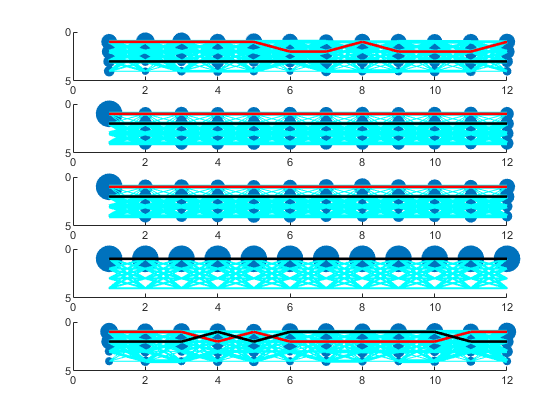

% https://kr.mathworks.com/help/matlab/ref/scatter.html
figure;

emission_plot = zeros(npair, 3, nbest * nframe);
for p = 1:npair
    for ibest = 1:nbest
        for iframe = 1:nframe
            emission_plot(p,1,(ibest-1) * nframe + iframe) = iframe;
            emission_plot(p,2,(ibest-1) * nframe + iframe) = ibest;
            emission_plot(p,3,(ibest-1) * nframe + iframe) = 1 + 400 * 10^(emission1(p, iframe, ibest));
        end
    end
end

hold on;
for p=1:npair
    subplot(npair,1,p);
    scatter(...
        squeeze(emission_plot(p, 1,:)), ... % x range (x data for scatter)
        squeeze(emission_plot(p, 2,:)), ... % y range (y data for scatter)
        squeeze(emission_plot(p, 3,:)), ... % radius
        'filled');     
    axis ij;
    ylim([0 nbest+1]); % for readability
end

hold on;
max_linewidth = 1+max(max(max(max(transition1))));
for p=1:npair
    subplot(npair, 1, p);
    for t = 2:nframe
        for n = 1:nbest
            for nprev = 1:nbest
                line([t-1 t], ... % x data
                    [nprev n], ... % y data
                    'LineWidth', 10^(transition1(p,t,n,nprev))*3,... % tuning
                    'Color','cyan');
            end
        end
    end
end

hold on;
for p = 1:npair
    subplot(npair,1,p);
    for t = 2:nframe
        line([t-1 t], [bestpath1(p,t-1,1) bestpath1(p,t,1)], ...
            'LineWidth', 2, ...
            'Color', 'red');
        line([t-1 t], [bestpath1(p,t-1,2) bestpath1(p,t,2)], ...
            'LineWidth', 2, ...
            'Color', 'black');
    end
end

## multi channel viterbi - state define

nbest2 = 2;
nstate = nbest2 ^ npair;
g = zeros(nstate, npair);
tmp_row = zeros(3,1);
l = 1;
for ibest = 1:nbest2
    [g, l] = fill_all_comb(1, npair, ibest, nbest2, tmp_row, g, l);
end
disp(g);

     1     1     1     1     1
     1     1     1     1     2
     1     1     1     2     1
     1     1     1     2     2
     1     1     2     1     1
     1     1     2     1     2
     1     1     2     2     1
     1     1     2     2     2
     1     2     1     1     1
     1     2     1     1     2
     1     2     1     2     1
     1     2     1     2     2
     1     2     2     1     1
     1     2     2     1     2
     1     2     2     2     1
     1     2     2     2     2
     2     1     1     1     1
     2     1     1     1     2
     2     1     1     2     1
     2     1     1     2     2
     2     1     2     1     1
     2     1     2     1     2
     2     1     2     2     1
     2     1     2     2     2
     2     2     1     1     1
     2     2     1     1     2
     2     2     1     2     1
     2     2     1     2     2
     2     2     2     1     1
     2     2     2     1     2
     2     2     2     2     1
     2     2     2     2     2



## multi channel viterbi - emission, trans prob

emission2 = zeros(nframe, nstate);
diff2 = zeros(nmic, nframe, nbest, nbest); % do not using 1st idx
transition2 = zeros(nframe, nstate, nstate); % do not using 1st idx

for t = 1:nframe
    for l = 1:nstate
        for m = 1:npair
            ibest = bestpath1(m, t, g(l,m));
            if gcc_nbest(m,t,ibest) > 0
                emission2(t, l)...
                    = emission2(t, l)...
                    + log10(gcc_nbest(m,t,ibest));
            end
            
        end
    end
end



for t = 2:nframe
    
    maxdiff2 = 0;
    for ibest = 1:nbest
        for jbest = 1:nbest
            for m = 1:npair-1 % why -1?
                diff2(m,t,ibest, jbest) = abs(tdoa_nbest(m,t,ibest) - tdoa_nbest(m,t-1,jbest));
                if maxdiff2 < diff2(m,t,ibest, jbest)
                    maxdiff2 = diff2(m,t,ibest, jbest);
                end
            end
        end
    end
    
    diff2(:,t,:,:) = log10( (1 + maxdiff2 - diff2(:,t,:,:)) / (2 + maxdiff2) );
    
    for l = 1:nstate
        for lprev = 1:nstate
            for m = 1:npair-1 % why -1?           
                ibest = bestpath1(m, t, g(l,m));
                jbest = bestpath1(m, t-1, g(lprev,m));
                
                transition2(t,l,lprev)...
                    = transition2(t,l,lprev)...
                    + diff2(m,t,ibest,jbest);
            end
        end
    end
           
end
disp(emission2(2,end));

  -4.530028148174052



disp(transition2(2,:,1));

  1 ~ 3번 열

  -0.009059314209036  -0.009059314209036  -0.009059314209036

  4 ~ 6번 열

  -0.009059314209036  -2.691204390582868  -2.691204390582868

  7 ~ 9번 열

  -2.691204390582868  -2.691204390582868  -2.691204390582868

  10 ~ 12번 열

  -2.691204390582868  -2.691204390582868  -2.691204390582868

  13 ~ 15번 열

  -5.373349466956699  -5.373349466956699  -5.373349466956699

  16 ~ 18번 열

  -5.373349466956699  -0.016436043267791  -0.016436043267791

  19 ~ 21번 열

  -0.016436043267791  -0.016436043267791  -2.698581119641622

  22 ~ 24번 열

  -2.698581119641622  -2.698581119641622  -2.698581119641622

  25 ~ 27번 열

  -2.698581119641622  -2.698581119641622  -2.698581119641622

  28 ~ 30번 열

  -2.698581119641622  -5.380726196015455  -5.380726196015455

  31 ~ 32번 열

  -5.380726196015455  -5.380726196015455



## multi channel viterbi - searching

back2_table = zeros(nframe, nstate);

bestpath2 = ones(nframe, 1); % state idx stored.

dC = ones(nframe, nstate) * -1000;
tC = ones(nframe, nstate);

R = ones(nframe, 1); % best prev state
F = ones(nframe, 1);

forwardTrans = zeros(nframe, nstate);
selfLoopTrans = zeros(nframe, nstate);


for l = 1:nstate
    dC(1,l) = emission2(1,l);
end


for t = 2:nframe
    for l = 1:nstate
        best_l_prev = R(t-1);
        back2_table(t,l) = best_l_prev;
        
        forwardTrans(t,l) = dC(t-1,best_l_prev) + 25 * transition2(t,l,best_l_prev);
        selfLoopTrans(t,l) = dC(t-1,l) + 25 * transition2(t,l,l);
        
        if selfLoopTrans(t,l) >= forwardTrans(t,l)
            dC(t,l) = selfLoopTrans(t,l) + emission2(t,l);
            tC(t,l) = tC(t-1,l);
        else
            dC(t,l) = forwardTrans(t,l) + emission2(t,l);
            tC(t,l) = t;
        end
    end
    
    [dummy, R(t)] = max(dC(t,:));
    F(t) = tC(t,R(t));
    
end

st = F(end);
bestpath2(st:end) = R(end);

while st > 2
    ed = st - 1;
    st = F(ed);
    bestpath2(st:ed) = R(ed);
end

viterbi_score = dC(end,R(end));

besttdoa = zeros(npair, nframe);
bestgcc2 = zeros(npair, nframe);

for t = 1:nframe
    for p = 1:npair
        l = bestpath2(t);
        ibest = bestpath1(p, t, g(l,p));
        besttdoa(p,t) = tdoa_nbest(p,t,ibest);
        bestgcc2(p,t) = gcc_nbest(p,t,ibest);
    end
end
disp(back2_table(:,:)'); % compare first mic pair trellis plot

     0     1     1     1     2     1     2     2     2     2     2     1
     0     1     1     1     2     1     2     2     2     2     2     1
     0     1     1     1     2     1     2     2     2     2     2     1
     0     1     1     1     2     1     2     2     2     2     2     1
     0     1     1     1     2     1     2     2     2     2     2     1
     0     1     1     1     2     1     2     2     2     2     2     1
     0     1     1     1     2     1     2     2     2     2     2     1
     0     1     1     1     2     1     2     2     2     2     2     1
     0     1     1     1     2     1     2     2     2     2     2     1
     0     1     1     1     2     1     2     2     2     2     2     1
     0     1     1     1     2     1     2     2     2     2     2     1
     0     1     1     1     2     1     2     2     2     2     2     1
     0     1     1     1     2     1     2     2     2     2     2     1
     0     1     1     1     2     1     2     2   



disp(besttdoa);

    -6     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0
     2    -4    -4     2    -4     2     2     2     2     2    -4     4



## multi channel viterbi - plot

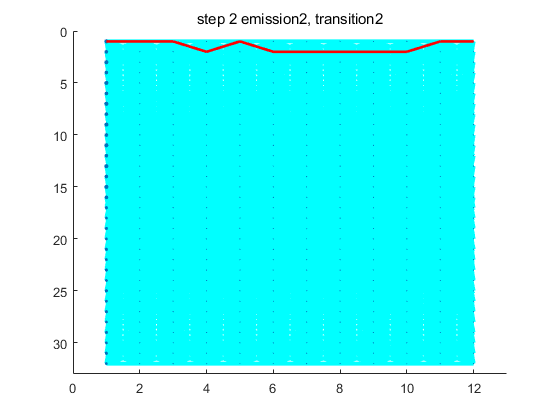

% https://kr.mathworks.com/help/matlab/ref/scatter.html
figure;

title(sprintf('step 2 emission2, transition2'));
for t = 2:nframe
    for l = 1:nstate
        for lprev = 1:nstate
            line([t-1 t], ... % x data
                [lprev l], ... % y data
                'LineWidth', 3*(exp(transition2(t,l,lprev))),... % tuning
                'Color','cyan');
            axis ij;
        end
    end
end

emission2_plot = zeros(3, nstate * nframe);

for l = 1:nstate
    for iframe = 1:nframe
        
       
        emission2_plot(1,(l-1) * nframe + iframe) = iframe;
        emission2_plot(2,(l-1) * nframe + iframe) = l;
        emission2_plot(3,(l-1) * nframe + iframe) = 1 + 400 * 10^(emission2(iframe, l));
    end
end

hold on;
scatter(...
    squeeze(emission2_plot(1,:)), ... % x range (x data for scatter)
    squeeze(emission2_plot(2,:)), ... % y range (y data for scatter)
    squeeze(emission2_plot(3,:)), ... % radius
    'filled');

hold on;
for t = 2:nframe
    line([t-1 t], [bestpath2(t-1) bestpath2(t)], ...
        'LineWidth', 2, ...
        'Color', 'red');
end


axis ij;
ylim([0 nstate+1]); % for readability
xlim([0 nframe+1]);

## compute local xcorr

tmp_localxcorr = zeros(nmic, nmic, nframe);
localxcorr = zeros(nmic, nframe);

mic2refpair = zeros(nmic,1);
mic2refpair(ref_mic) = 0;

for p = 1:npair
    m = micpair(ref_mic,p);
    mic2refpair(m) = p;
end

for t = 1:nframe
    ref_st = (t-1) * 4000 + 1;
    ref_ed = min(ref_st + 8000 - 1, nsample);
    
    for m1 = 1:(nmic-1)
        for m2 = (m1+1):nmic
            
            if m1 == ref_mic
                st1 = ref_st;
                ed1 = ref_ed;
            else
                p = mic2refpair(m1);
                st1 = max(1,ref_st + besttdoa(p,t));
                ed1 = min(nsample, ref_ed + besttdoa(p,t));
            end
            
            if m2 == ref_mic
                st2 = ref_st;
                ed2 = ref_ed;
            else
                p = mic2refpair(m2);
                st2 = max(1,ref_st + besttdoa(p,t));
                ed2 = min(nsample, ref_ed + besttdoa(p,t));
            end
            
            buf1 = x(m1,st1:ed1);
            buf2 = x(m2,st2:ed2);
            
            ener1 = sum(buf1(:).^2);
            ener2 = sum(buf2(:).^2);
            
            min_ed = min(ed1-st1, ed2-st2) + 1;
            tmp_localxcorr(m1,m2,t)...
                = sum(...
                buf1(1:min_ed) .* buf2(1:min_ed)...
                / (ener1 * ener2));
            
            if tmp_localxcorr(m1,m2,t) < 0
                tmp_localxcorr(m1,m2,t) = 0;
            end
            
            tmp_localxcorr(m2,m1,t) = tmp_localxcorr(m1,m2,t);
        end
    end
end

disp(tmp_localxcorr(1,2:3,1));

   0.000698030059640   0.057655645698108




localxcorr = squeeze(sum(tmp_localxcorr,1));
disp(localxcorr);

  1 ~ 3번 열

   0.397481828090729   0.272221311968858   0.549831429382502
   0.002428795872431   0.005991739961208   0.011247254873043
   0.186393330242774                   0   0.002722408652724
   0.715193264562037   0.414665250919336   0.893735914333955
   0.607615570764660   0.327711969658177   0.756122440655160

  4 ~ 6번 열

   0.645235383824703   0.470792710453255   0.690668782684766
   0.004307078074065   0.002945669327416   0.004302080955592
   0.141449692662963                   0   0.006917319779727
   1.235582243838077   0.708176751949193   1.011422635724574
   1.140483857709310   0.572504011494178   0.925135324078567

  7 ~ 9번 열

   0.813100606742873   0.526430115188119   0.253807332047596
   0.007271616997500   0.001950581914052   0.006902963426551
   0.232380957256995   0.108274854763060   0.056979231306526
   1.305816345787604   0.954577045883116   0.439465023250163
   1.189136571512724   0.867979358789862   0.392843880577642

  10 ~ 12번 열

   0.218957123065576   0.2812225

## compute sum weight

out_weight = ones(nmic, nframe) * ( 1 / nmic);
alpha = 0.05;


for t = 1:nframe
    
    if sum(localxcorr(:,t)) == 0
        localxcorr(:,t) = 1 / nmic;
    end
    
    localxcorr(:,t) = localxcorr(:,t) / sum(localxcorr(:,t));
    localxcorr_sum_nonref = 0;
    localxcorr_sum = 0;
    
    for m = 1:nmic
        if m == ref_mic
             out_weight(m,t) = ...
            (1-alpha) * out_weight(m,max(1,t-1)) ...
            + alpha * localxcorr(m,t);    
        
        else
            p = mic2refpair(m);
            if noise_filter(p,t) == 0
                out_weight(m,t) = ...
                    (1-alpha) * out_weight(m,max(1,t-1)) ...
                    + alpha * localxcorr(m,t);    
            end
            
            localxcorr_sum_nonref = localxcorr_sum_nonref + localxcorr(m,t);
        end 
    end
    
    if sum(localxcorr(:,t)) == 0
        out_weight(:,t) = 1;
    end
    
    for m = 1:nmic
        if m ~= ref_mic
            if (localxcorr(m,t) / localxcorr_sum_nonref) < (1 / (10 * (nmic-1)))
                out_weight(m,t) = 0;
            end
        end
    end
    out_weight(:,t) = out_weight(:,t) / sum(out_weight(:,t));
    
end

disp(mic2refpair');

     1     2     3     4     5



disp(out_weight);

  1 ~ 3번 열

   0.245885478956445   0.322110404440794   0.318524450164241
                   0                   0                   0
   0.245382299188534                   0                   0
   0.256094509453133   0.343865208632611   0.346968271223715
   0.252637712401888   0.334024386926595   0.334507278612044

  4 ~ 6번 열

   0.261154873772821   0.310853617665045   0.308465072554650
                   0                   0                   0
   0.166986883237902                   0                   0
   0.291497846326962   0.353159632502212   0.354744087460624
   0.280360396662314   0.335986749832743   0.336790839984726

  7 ~ 9번 열

   0.254467355389486   0.242976318106568   0.238440845782640
                   0                   0                   0
   0.167137097825062   0.192496730621572   0.197170482242763
   0.297011443074925   0.290255291181525   0.290678314921631
   0.281384103710528   0.274271660090335   0.273710357052966

  10 ~ 12번 열

   0.234903319204833   0.2329763

## Channel sum

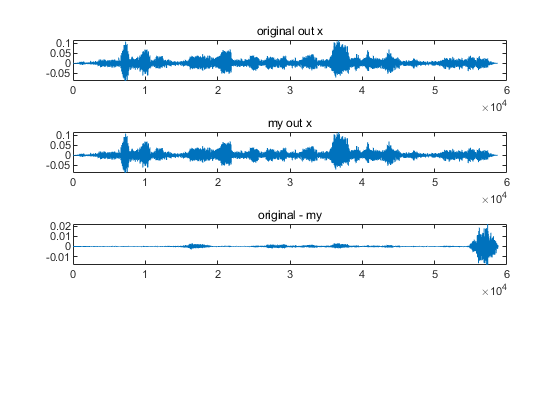

out_x = zeros(1,nsample);

% figure;
for t = 1:nframe
    ref_st = (t-1) * 4000 + 1;
    ref_ed = min(ref_st + 8000 - 1, nsample);
    
    for m = 1:nmic   
        if m == ref_mic
            st = ref_st;
            ed = ref_ed;
        else
            p = mic2refpair(m);
            st = max(1,ref_st + besttdoa(p,t));
            ed = min(nsample, ref_ed + besttdoa(p,t));
        end
       
        triwin = triang(8000)';
%         if t == 1
%             triwin(1:4000) = 1;
%         end
        
         diff = 0;

        if (ref_ed - ref_st) ~= (ed - st) % if buf is small (always)
                diff = ref_ed - ed;
        end
        out_x(ref_st+diff:ref_ed)...
            = out_x(ref_st+diff:ref_ed)...   
            + (squeeze(x(m,st:ed))...
            * out_weight(m,t)...
            .* triwin(1:min(8000,ed-st+1))...
            * overall_weight);
            
        
            %.* triwin(min(8000,min_ed-ref_st+1))...
            %* out_weight(m,t));
%         plot(out_x);
    end
end


while ref_ed < nsample    
    ref_st = ref_st + 4000;
    ref_ed = min(ref_st + 8000 - 1, nsample);
    
    for m = 1:nmic
        if m == ref_mic
            st = ref_st;
            ed = ref_ed;
        else
            p = mic2refpair(m);
            st = max(1,ref_st + besttdoa(p,t));
            ed = min(nsample, ref_ed + besttdoa(p,t));
        end
        if st > ed
            continue;
        end
        buf = squeeze(x(m,st:ed));
        diff = (ref_ed - ref_st) - (ed-st);
        if diff > 0
            buf = [buf, zeros(1,diff)];
        else
            buf = buf(1:end-diff);
        end
        
        triwin = triang(8000)';
    
        out_x(ref_st:ref_ed)...
                = out_x(ref_st:ref_ed)...   
                + (buf...
                * out_weight(m,t)...
                .* triwin(1:min(8000,size(buf,2)))...
                * overall_weight);
    
    end
end



audiowrite(outname,out_x,16000);

out_x = audioread(outname);
orig_out_x = audioread(orig_outname);

subplot(4,1,1); plot(orig_out_x); title('original out x');
subplot(4,1,2); plot(orig_out_x); title('my out x');
subplot(4,1,3); plot(out_x-orig_out_x); title('original - my');


nshift = nwin / 2; % 4000
ed = (nframe-1)*nshift;
disp(mean((out_x-orig_out_x).^2));

     2.165924584430555e-06



function [table, l] = fill_all_comb(ipair, npair, ibest, nbest, tmp_row, table, l)
    tmp_row(ipair) = ibest;
    %fprintf('ipair: %d ibest: %d l: %d\n', ipair, ibest, l);
    
    if ipair == npair    
        for j = 1:npair
            table(l, j) = tmp_row(j);
        end
        l = l + 1;
    else
        for ibest = 1:nbest
            [table, l] = fill_all_comb(ipair + 1, npair, ibest, nbest, tmp_row, table, l);
        end
    end
end

function [max_val, idx] = maxk(list, k, nmask)
    candi_list = zeros(length(list(:)),1);
    for i = 2:(length(list(:))-1)
        if list(i-1) < list(i) && list(i+1) < list(i)
            candi_list(i) = list(i);
%             list(i-1) = -9999;
%             list(i+1) = -9999;
        end
    end

    max_val = zeros(k, 1);
    idx = zeros(k,1);
    for i = 1:k
        [max_val(i), idx(i)] = max(candi_list);
        st = max(idx(i)-nmask+1, 1);
        ed = min(length(candi_list(:)), idx(i)+nmask-1);
        candi_list(st:ed) = 0;
    end
end